# Semantic Segmentation Using Deep Learning

This example creates the SegNet network with weights initialized from the VGG-16 network. To get VGG-16, install [Deep Learning Toolbox™ Model for VGG-16 Network](https://www.mathworks.com/help/nnet/ref/vgg16.html). After installation is complete, run the following code to verify that the installation is correct.

Verify GPU

% gpuEnvObj = coder.gpuEnvConfig
% gpuEnvObj.BasicCodegen = 1
% gpuEnvObj.BasicCodeexec = 1
% gpuEnvObj.DeepLibTarget = 'cudnn'
% gpuEnvObj.DeepCodeexec = 1
% gpuEnvObj.DeepCodegen = 1
% results = coder.checkGpuInstall(gpuEnvObj)
% webcamlist
% cam = webcam(2)

vgg16();
%load tiles dataset
% pretrainedNetwork = fullfile('D:\TAEvianita\mencoba\deeplabv3plusResnet18CamVid.mat') %new
dataDir = fullfile('D:\TAEvianita');
imgDir = fullfile('D:\TAEvianita\bismillah');
imds = imageDatastore(imgDir);
labelDir = fullfile('D:\TAEvianita\bismillah\PixelLabelData_1');

**resize image**

% imageFolder = fullfile('D:\TAEvianita\video','imagesResized',filesep);
% imds = resizeTilesImages(imds, imageFolder)
% labelFolder = fullfile('D:\TAEvianita\video\1','labelsResized',filesep);
% pxds = resizeTilesPixelLabels(pxds, labelFolder)

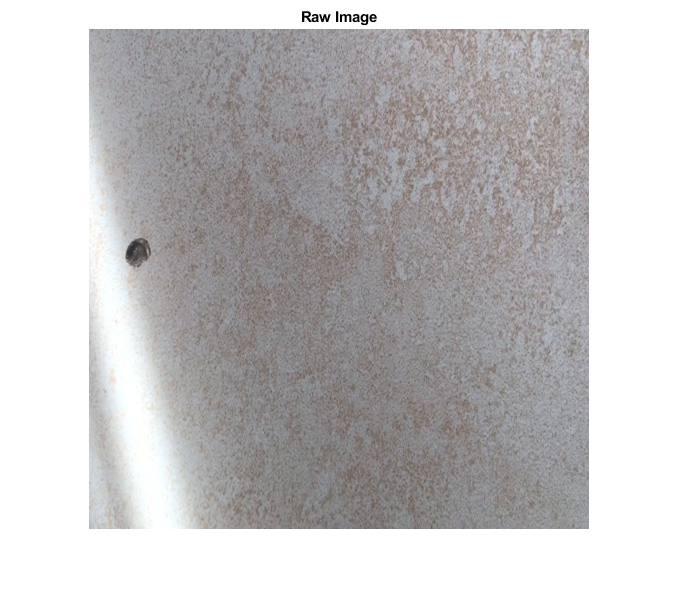

%suppress image display warnings
warning('off','images:Initsize:adjustingMag');
pic_num = 250;
I_raw = readimage(imds,pic_num);
I = readimage(imds,pic_num);
I = histeq(I_raw);
figure
imshow(I_raw);
drawnow
title('Raw Image');

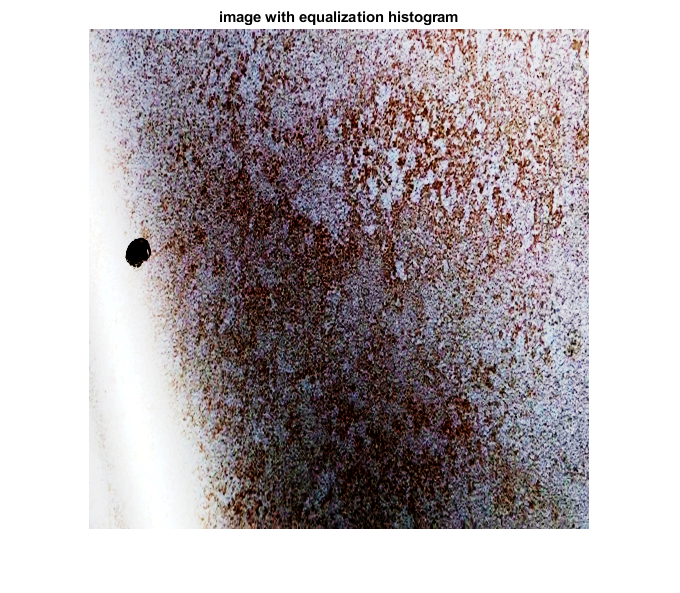

figure 
imshow(I);
drawnow
title('image with equalization histogram');

**Load Tiles Pixel-Labeled Images**

Use [`pixelLabelDatastore`](https://localhost:31515/static/help/vision/ref/pixellabeldatastore.html) to load CamVid pixel label image data. A `pixelLabelDatastore` encapsulates the pixel label data and the label ID to a class name mapping.

Following the procedure used in original SegNet paper [1], group the 32 original classes in CamVid to 11 classes. Specify these classes.

To reduce 32 classes into 11, multiple classes from the original dataset are grouped together. For example, "Car" is a combination of "Car", "SUVPickupTruck", "Truck_Bus", "Train", and "OtherMoving". Return the grouped label IDs by using the supporting function `camvidPixelLabelIDs`, which is listed at the end of this example

pixelLabelID = [1 2];
labelIDs = tilesPixelLabelIDs() 

labelIDs = 2×1 cell array
    {1×3 double}
    {1×3 double}


classes= ["crack" "background"]

classes = 1×2 string array
    "crack"    "background"


pxds = pixelLabelDatastore(labelDir,classes,pixelLabelID)

pxds =   PixelLabelDatastore with properties:

                       Files: {410×1 cell}
                  ClassNames: {2×1 cell}
                    ReadSize: 1
                     ReadFcn: @readDatastoreImage
    AlternateFileSystemRoots: {}


Use the classes and label IDs to create the `pixelLabelDatastore.`

Read and display one of the pixel-labeled images by overlaying it on top of an image

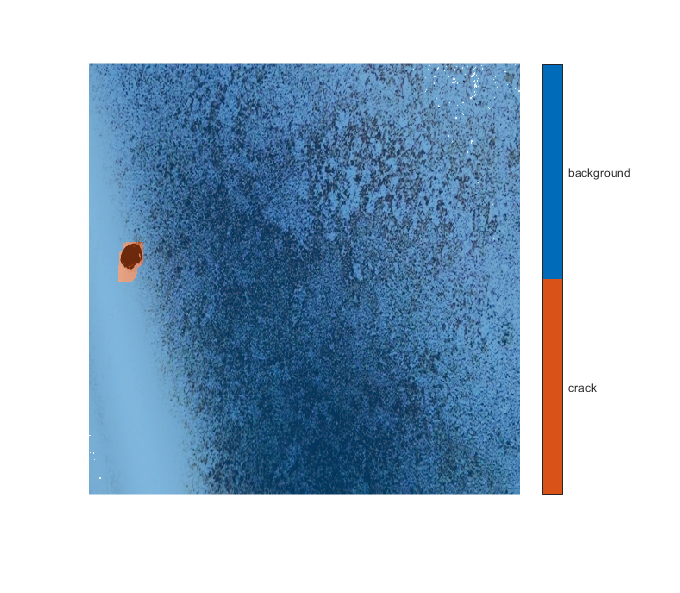

C = readimage (pxds,pic_num);
cmap = tilesColorMap;
B = labeloverlay(I,C,'ColorMap',cmap);
figure
imshow(B);
drawnow
pixelLabelColorbar(cmap,classes);

**Analyze Dataset Statistics**

To see the distribution of class labels in the CamVid dataset, use [`countEachLabel`](https://localhost:31515/static/help/vision/ref/pixellabelimagedatastore.counteachlabel.html). This function counts the number of pixels by class label.

tbl = countEachLabel(pxds)

tbl = 2×3 table
         Name         PixelCount    ImagePixelCount
    ______________    __________    _______________

    {'crack'     }    8.5792e+05        1.02e+08   
    {'background'}     1.011e+08       1.025e+08   


frequency = tbl.PixelCount/sum(tbl.PixelCount)

frequency =     0.0084
    0.9916


figure

Visualize the pixel counts by class.

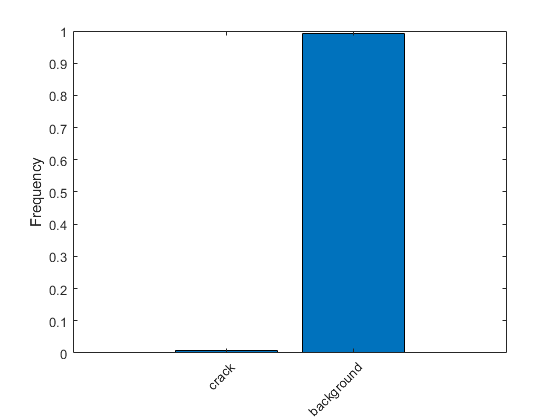

bar(1:numel(classes),frequency);
xticks(1:numel(classes));
xticklabels(tbl.Name);
xtickangle(45);
ylabel('Frequency');

**Prepare Training and Test Sets**

SegNet is trained using 60% of the images from the dataset. The rest of the images are used for testing. The following code randomly splits the image and pixel label data into a training and test set.

%[imdsTrain, imdsTest, pxdsTrain, pxdsTest] = partitionTilesData(imds,pxds);
[imdsTrain, imdsTest, imdsVal, pxdsTrain, pxdsVal, pxdsTest] = partitionTilesData(imds,pxds);

numVal = 49

numTrainingImages = numel(imdsTrain.Files)

numTrainingImages = 246

numTestingImages = numel(imdsTest.Files)

numTestingImages = 164

numValImages = numel(imdsVal.Files)

numValImages = 49

**reate the Network**

Use [`segnetLayers`](https://localhost:31515/static/help/vision/ref/segnetlayers.html) to create a SegNet network initialized using VGG-16 weights. `segnetLayers`automatically performs the network transformations needed to transfer the weights from VGG-16 and adds the additional layers required for semantic segmentation. The output of `segnetLayers` is a `LayerGraph`object representing SegNet. A `LayerGraph` object encapsulates the network layers and the connections between the layers.

imageSize = [500 500 3];
numClasses = numel(classes);
%segnet layers return segnet network layer, lgraph, that is pretrained with

lgraph = segnetLayers(imageSize,numClasses,'vgg16')

lgraph =   LayerGraph with properties:

         Layers: [91×1 nnet.cnn.layer.Layer]
    Connections: [100×2 table]
     InputNames: {'inputImage'}
    OutputNames: {'pixelLabels'}


%lgraph initially has 91 layers
% lgraph.Layers
% % % % %%plot the 91 layer lgraph
% fig1 = figure ('Position',[100,100,100,1100])
% subplot(1,2,1)
% plot(lgraph)
% axis off
% axis tight
% title('complete layers graph')
% 
% subplot(1,2,2)
% plot(lgraph)
% xlim([2.862 3.200])
% ylim([-0.9 10.9])
% axis off
% title('last 9 layers graph')

**Balance Classes Using Class Weighting**

As shown earlier, the classes in CamVid are not balanced. To improve training, you can use class weighting to balance the classes. Use the pixel label counts computed earlier with [`countEachLabel`](https://localhost:31515/static/help/vision/ref/pixellabelimagedatastore.counteachlabel.html) and calculate the median frequency class weights.

imageFreq = tbl.PixelCount ./ tbl.ImagePixelCount

imageFreq =     0.0084
    0.9863


classWeights = median(imageFreq) ./ imageFreq

classWeights =    59.1332
    0.5043


Specify the class weights using a [`pixelClassificationLayer`](https://localhost:31515/static/help/vision/ref/nnet.cnn.layer.pixelclassificationlayer.html).

% pxLayer = pixelClassificationLayer('Name','labels','classNames',tbl.Name,...
    %'ClassWeights',classWeights);
pxLayer = pixelClassificationLayer('Name','pixelLabels','classes',tbl.Name,...
    'ClassWeights',classWeights)

pxLayer =   PixelClassificationLayer with properties:

            Name: 'pixelLabels'
         Classes: [crack    background]
    ClassWeights: [2×1 double]
      OutputSize: 'auto'

   Hyperparameters
    LossFunction: 'crossentropyex'


Update the SegNet network with the new `pixelClassificationLayer` by removing the current`pixelClassificationLayer` and adding the new layer. The current `pixelClassificationLayer` is named 'pixelLabels'. Remove it using [`removeLayers`](https://localhost:31515/static/help/deeplearning/ref/removelayers.html), add the new one using [`addLayers`](https://localhost:31515/static/help/deeplearning/ref/addlayers.html), and connect the new layer to the rest of the network using [`connectLayers`](https://localhost:31515/static/help/deeplearning/ref/connectlayers.html).

**Select Training Options**

The optimization algorithm used for training is stochastic gradient descent with momentum (SGDM). Use[`trainingOptions`](https://localhost:31515/static/help/deeplearning/ref/trainingoptions.html) to specify the hyperparameters used for SGDM.

pximdsVal = pixelLabelImageDatastore(imdsVal,pxdsVal)

pximdsVal =   pixelLabelImageDatastore with properties:

                  Images: {49×1 cell}
          PixelLabelData: {49×1 cell}
              ClassNames: {2×1 cell}
        DataAugmentation: 'none'
      ColorPreprocessing: 'none'
              OutputSize: []
          OutputSizeMode: 'resize'
           MiniBatchSize: 1
         NumObservations: 49
    DispatchInBackground: 0



options = trainingOptions('sgdm', ...
    'ExecutionEnvironment','gpu',...
    'LearnRateSchedule','piecewise',...
    'LearnRateDropPeriod',10,...
    'LearnRateDropFactor',0.3,...
    'Momentum',0.9, ...
    'InitialLearnRate',1e-3, ...
    'L2Regularization',0.005, ...
    'ValidationData',pximdsVal,...
    'MaxEpochs',5, ...  
    'MiniBatchSize',1, ...
    'Shuffle','every-epoch', ...
    'CheckpointPath','D:\TAEvianita\video\tilesdatase', ...
    'VerboseFrequency',2,...
    'Plots','training-progress',...
    'ValidationPatience', 4);

A minibatch size of 4 is used to reduce memory usage while training. You can increase or decrease this value based on the amount of GPU memory you have on your system.

In addition, `'CheckpointPath'` is set to a temporary location. This name-value pair enables the saving of network checkpoints at the end of every training epoch. If training is interrupted due to a system failure or power outage, you can resume training from the saved checkpoint. Make sure that the location specified by`'CheckpointPath'` has enough space to store the network checkpoints. For example, saving 100 SegNet checkpoints requires ~11 GB of disk space because each checkpoint is 107 MB.

**Data Augmentation**

Data augmentation is used during training to provide more examples to the network because it helps improve the accuracy of the network. Here, random left/right reflection and random X/Y translation of +/- 10 pixels is used for data augmentation. Use the [`imageDataAugmenter`](https://localhost:31515/static/help/deeplearning/ref/imagedataaugmenter.html) to specify these data augmentation parameters

augmenter = imageDataAugmenter('RandXReflection',true,...
    'RandXTranslation',[-10 10],'RandYTranslation',[-10 10]);

`imageDataAugmenter` supports several other types of data augmentation. Choosing among them requires empirical analysis and is another level of hyperparameter tuning.**Start Training**

Combine the training data and data augmentation selections using [`pixelLabelImageDatastore`](https://localhost:31515/static/help/vision/ref/pixellabelimagedatastore.html). The`pixelLabelImageDatastore` reads batches of training data, applies data augmentation, and sends the augmented data to the training algorithm

pximds = pixelLabelImageDatastore(imdsTrain,pxdsTrain, ...
    'DataAugmentation',augmenter)

pximds =   pixelLabelImageDatastore with properties:

                  Images: {246×1 cell}
          PixelLabelData: {246×1 cell}
              ClassNames: {2×1 cell}
        DataAugmentation: [1×1 imageDataAugmenter]
      ColorPreprocessing: 'none'
              OutputSize: []
          OutputSizeMode: 'resize'
           MiniBatchSize: 1
         NumObservations: 246
    DispatchInBackground: 0


% cfg = coder.gpuConfig('mex');
% cfg.TargetLang = 'C++';
% cfg.DeepLearningConfig = coder.DeepLearningConfig('tensorrt');
% codegen -config cfg resnet_predict -args {ones(500,500,3)} -report

Start training using [`trainNetwork`](https://localhost:31515/static/help/deeplearning/ref/trainnetwork.html) if the `doTraining` flag is true. Otherwise, load a pretrained network.

Note: The training was verified on an NVIDIA™ Titan X with 12 GB of GPU memory. If your GPU has less memory, you may run out of memory. If this happens, try setting '`MiniBatchSize'` to 1 in using`trainingOptions`. Training this network takes about 5 hours. Depending on your GPU hardware, it can take even longer.

doTraining = false;
if doTraining
    [net,info] = trainNetwork(pximds,lgraph,options);
    save ('D:\TAEvianita\video\tilesdatase\Pretraineddata.mat','net');
    disp('NN trained')
else
    %load the pre-trained network
     data = load('D:\TAEvianita\video\tilesdatase\Pretraineddata.mat')
     net = data.net
end

data = struct with fields:
    net: [1×1 DAGNetwork]


net =   DAGNetwork with properties:

         Layers: [91×1 nnet.cnn.layer.Layer]
    Connections: [100×2 table]
     InputNames: {'inputImage'}
    OutputNames: {'pixelLabels'}


**Test Network on One Image**

As a quick sanity check, run the trained network on one test image.

webcamlist;
cam = webcam(1);

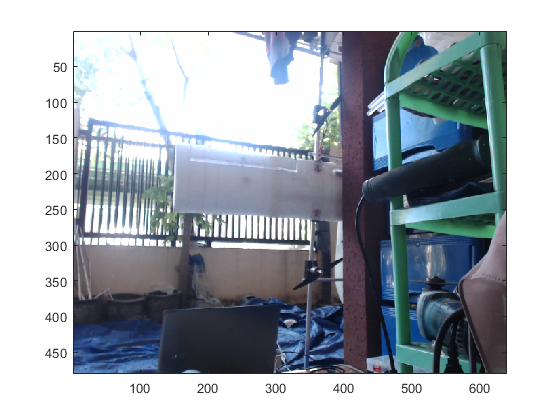

for i = 1:500
    img = snapshot(cam);
    image(img);
    I= imresize (img,[500 500]);

%I = imread('D:\TAEvianita\datatesting\resized\7test.jpg');
    %Ib = readimage(pxdsTest,1);
    %BC = labeloverlay(I, Ib,'Colormap',cmap,'Transparency',0.5);
    C = semanticseg(I, net);
    B = labeloverlay(I,C,'Colormap',cmap,'Transparency',0.5);%cb

% imshowpair (B,I,'montage')
% pixelLabelColorbar(cmap, classes)
% title ('prediction vs groundtruth')
imagesc (B)
end


delete(cam)

%pixelLabelColorbar(cmap, classes)
% expectedResult = readimage(pxdsTest,1);
% actual = uint8(C);
% expected = uint8(expectedResult);
% imshowpair(actual,expected)
% iou = jaccard(C,expectedResult);
% % [recall,precision,prediction]=bfscore(C,expectedResult)
% table(classes',iou)

% iou = bfscore(C,expectedResult);
% [recall,precision,prediction]=bfscore(C,expectedResult)
% table(classes',recall ,precision, iou)

%predict_scores = segnet_predict_mex(CB);
% [~,argmax] = max(predict_scores,[],3);  
% 
% I = readimage(imdsTest,1);
% C = semanticseg(I, lgraph);

display the result

Compare the results in `C` with the expected ground truth stored in `pxdsTest`. The green and magenta regions highlight areas where the segmentation results differ from the expected ground truth.

Visually, the semantic segmentation results overlap well for classes such as road, sky, and building. However, smaller objects like pedestrians and cars are not as accurate. The amount of overlap per class can be measured using the intersection-over-union (IoU) metric, also known as the Jaccard index. Use the[`jaccard`](https://localhost:31515/static/help/images/ref/jaccard.html) function to measure IoU

The IoU metric confirms the visual results. Road, sky, and building classes have high IoU scores, while classes such as pedestrian and car have low scores. Other common segmentation metrics include the [`dice`](https://localhost:31515/static/help/images/ref/dice.html)and the [`bfscore`](https://localhost:31515/static/help/images/ref/bfscore.html) contour matching score.**Evaluate** **Trained** **Network**

To measure accuracy for multiple test images, run [`semanticseg`](https://localhost:31515/static/help/vision/ref/semanticseg.html) on the entire test set. A minibatch size of 4 is used to reduce memory usage while segmenting images. You can increase or decrease this value based on the amount of GPU memory you have on your system.

pxdsResults = semanticseg(imdsTest,net, ...
    'MiniBatchSize',1, ...
    'WriteLocation','D:\TAEvianita\bismillah\evaluatesemanticseg', ...
    'Verbose',false);

`semanticseg` returns the results for the test set as a `pixelLabelDatastore` object. The actual pixel label data for each test image in `imdsTest` is written to disk in the location specified by the `'WriteLocation'`parameter. Use [`evaluateSemanticSegmentation`](https://localhost:31515/static/help/vision/ref/evaluatesemanticsegmentation.html) to measure semantic segmentation metrics on the test set results.

metrics = evaluateSemanticSegmentation(pxdsResults,pxdsTest,...
    'Verbose',true)

metrics.DataSetMetrics

metrics.ClassMetrics


Although the overall dataset performance is quite high, the class metrics show that underrepresented classes such as `Pedestrian`, `Bicyclist`, and `Car` are not segmented as well as classes such as `Road`, `Sky`, and`Building`. Additional data that includes more samples of the underrepresented classes might help improve the results.

**Supporting Functions**

function labelIDs = tilesPixelLabelIDs()
% Return the label IDs corresponding to each class.
%
% The CamVid dataset has 32 classes. Group them into 11 classes following
% the original SegNet training methodology [1].
%
% The 11 classes are:
%   "Sky" "Building", "Pole", "Road", "Pavement", "Tree", "SignSymbol",
%   "Fence", "Car", "Pedestrian",  and "Bicyclist".
%
% CamVid pixel label IDs are provided as RGB color values. Group them into
% 11 classes and return them as a cell array of M-by-3 matrices. The
% original CamVid class names are listed alongside each RGB value. Note
% that the Other/Void class are excluded below.
labelIDs = { ...
    % "crack"
    [
    217 82 24 ;...% "crack"
    ]
    % "background"
    [ 
    0 107 185;...%"background"
    ]
    };
end
function pixelLabelColorbar(cmap, classes)
% Add a colorbar to the current axis. The colorbar is formatted
% to display the class names with the color.

colormap(gca,cmap)

% Add colorbar to current figure.
c = colorbar('peer', gca);

% Use class names for tick marks.
c.TickLabels = classes;
numClasses = size(cmap,1);

% Center tick labels.
c.Ticks = 1/(numClasses*2):1/numClasses:1;

% Remove tick mark.
c.TickLength = 0;
end
function cmap = tilesColorMap()
% Define the colormap used by CamVid dataset.

cmap = [
   217 82 24  % crack
     0 107 185   % background
    ];

% Normalize between [0 1].
cmap = cmap ./ 255;
end

%function [imdsTrain, imdsTest, pxdsTrain,...
    %pxdsTest] = partitionTilesData(imds,pxds)
function [imdsTrain, imdsTest, imdsVal, pxdsTrain, pxdsVal,...
    pxdsTest] = partitionTilesData(imds,pxds)
% Partition CamVid data by randomly selecting 60% of the data for training. The
% rest is used for testing.
    
% Set initial random state for example reproducibility.
rng(0); 
numFiles = numel(imds.Files);
shuffledIndices = randperm(numFiles);

% Use 60% of the images for training.
N = round(0.60 * numFiles);
trainingIdx = shuffledIndices(1:N);

%use 20% of the images for validation
numVal = round(0.20 * N)
valIdx = shuffledIndices(N+1:N+numVal);

% Use the rest for testing.
testIdx = shuffledIndices(N+1:end);

% Create image datastores for training and test.
trainingImages = imds.Files(trainingIdx);
valImages = imds.Files(valIdx);
testImages = imds.Files(testIdx);

imdsTrain = imageDatastore(trainingImages);
imdsVal = imageDatastore(valImages);
imdsTest = imageDatastore(testImages);

% Extract class and label IDs info.
classes = pxds.ClassNames;
labelIDs = tilesPixelLabelIDs();
labelIDs = 1:numel(pxds.ClassNames);

% Create pixel label datastores for training and test.
trainingLabels = pxds.Files(trainingIdx);
valLabels = pxds.Files(valIdx);
testLabels = pxds.Files(testIdx);

pxdsTrain = pixelLabelDatastore(trainingLabels, classes, labelIDs);
pxdsVal = pixelLabelDatastore(valLabels,classes, labelIDs);
pxdsTest = pixelLabelDatastore(testLabels, classes, labelIDs);
end

function imds = resizeTilesImages(imds, imageFolder)
% Resize images to [360 480].

if ~exist(imageFolder,'dir') 
    mkdir(imageFolder)
else
    imds = imageDatastore(imageFolder);
    return; % Skip if images already resized
end

reset(imds)
while hasdata(imds)
    % Read an image.
    [I,info] = read(imds);     
    
    % Resize image.
    I = imresize(I,[500 500]);    
    
    % Write to disk.
    [~, filename, ext] = fileparts(info.Filename);
    imwrite(I,[imageFolder filename ext])
end

imds = imageDatastore(imageFolder);
end
function pxds = resizeTilesPixelLabels(pxds, labelFolder)
% Resize pixel label data to [360 480].

classes = pxds.ClassNames;
labelIDs = 1:numel(classes);
if ~exist(labelFolder,'dir')
    mkdir(labelFolder)
else
    pxds = pixelLabelDatastore(labelFolder,classes,labelIDs);
    return; % Skip if images already resized
end

reset(pxds)
while hasdata(pxds)
    % Read the pixel data.
    [C,info] = read(pxds);
    
    % Convert from categorical to uint8.
    L = uint8(C);
    
    % Resize the data. Use 'nearest' interpolation to
    % preserve label IDs.
    L = imresize(L,[500 500],'nearest');
    
    % Write the data to disk.
    [~, filename, ext] = fileparts(info.Filename);
    imwrite(L,[labelFolder filename ext])
end

labelIDs = 1:numel(classes);
pxds = pixelLabelDatastore(labelFolder,classes,labelIDs);
end

sumber : [https://www.mathworks.com/videos/deep-learning-demystified-system-design-and-implementation-1510587290588.html](https://www.mathworks.com/videos/deep-learning-demystified-system-design-and-implementation-1510587290588.html)